## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

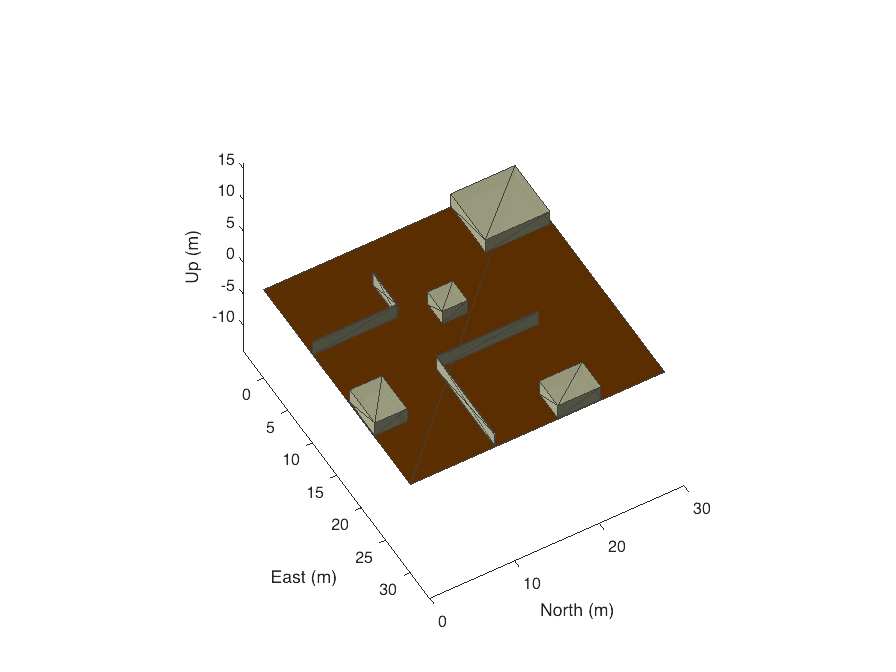

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment3();
show3D(scenario);
lightangle(-45,30);
view(60,50);

## Load the agent and create the simulink things

contents = load("experiments_comparison_points/experiment_3_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.PRIORITISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});

    %if collisions > 0 || deadlocks > 0 
    %    [obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
    %    travelDistances = simulateExperiment(waypoints, tasks, robots, scenario);
    %end
end

Elapsed time is 2.342303 seconds.


ans =      4     2


ans =     10    14


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.663891 seconds.


ans =      3    10


ans =      9    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.409321 seconds.


ans =     17     8


ans =      3    10


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.956604 seconds.


ans =      8    21


ans =      4     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.691735 seconds.


ans =      4     2


ans =     10    14


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.024489 seconds.


ans =     15     6


ans =      9    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.234387 seconds.


ans =     15     6


ans =      8    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.095815 seconds.


ans =     15     6


ans =     17     8


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.831160 seconds.


ans =      3    10


ans =      9    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.886694 seconds.


ans =      4     2


ans =     21    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.474909 seconds.


ans =     21    21


ans =     16     9


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.098077 seconds.


ans =     11    24


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.881733 seconds.


ans =      8    21


ans =     16     9


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.172963 seconds.


ans =     16     9


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.553661 seconds.


ans =      8    21


ans =     22    24


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.134749 seconds.


ans =      9    25


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.806119 seconds.


ans =     15     6


ans =     21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.652767 seconds.


ans = 1×2
    11    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.476782 seconds.


ans = 1×2
     9    25


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.045396 seconds.


ans = 1×2
    21    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.089948 seconds.


ans = 1×2
     9    25


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.847224 seconds.


ans = 1×2
    17     8


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.686997 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.101912 seconds.


ans = 1×2
     9    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.549978 seconds.


ans = 1×2
    10    14


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.196627 seconds.


ans = 1×2
    15     6


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.019207 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.771144 seconds.


ans = 1×2
    22    24


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.472593 seconds.


ans = 1×2
    21    21


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.142506 seconds.


ans = 1×2
    15     6


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.067009 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.135047 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.637119 seconds.


ans = 1×2
     9    25


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.941628 seconds.


ans = 1×2
    21    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.698350 seconds.


ans = 1×2
     3    10


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.855078 seconds.


ans = 1×2
    10    14


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.258665 seconds.


ans = 1×2
    21    21


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.811773 seconds.


ans = 1×2
    15     6


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.134022 seconds.


ans = 1×2
    15     6


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.350339 seconds.


ans = 1×2
     9    25


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.447184 seconds.


ans = 1×2
     9    21


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.492292 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.500763 seconds.


ans = 1×2
     9    25


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.229267 seconds.


ans = 1×2
     3    10


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.257353 seconds.


ans = 1×2
     3    10


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.574799 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.455330 seconds.


ans = 1×2
    16     9


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.156713 seconds.


ans = 1×2
    16     9


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.033973 seconds.


ans = 1×2
     3    10


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.697435 seconds.


ans = 1×2
    10    14


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.509117 seconds.


ans = 1×2
    10    14


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.404809 seconds.


ans = 1×2
    21    21


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.157526 seconds.


ans = 1×2
     9    21


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.759662 seconds.


ans = 1×2
    11    24


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.035493 seconds.


ans = 1×2
     9    25


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.610714 seconds.


ans = 1×2
     9    21


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.791729 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.875727 seconds.


ans = 1×2
    22    24


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.143907 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.884454 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.638957 seconds.


ans = 1×2
     9    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.230840 seconds.


ans = 1×2
     9    25


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.604815 seconds.


ans = 1×2
    15     6


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.805258 seconds.


ans = 1×2
    15     6


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.940626 seconds.


ans = 1×2
    15     6


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.811608 seconds.


ans = 1×2
    11    24


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.863845 seconds.


ans = 1×2
    21    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.746153 seconds.


ans = 1×2
     9    25


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.124815 seconds.


ans = 1×2
    11    24


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.507798 seconds.


ans = 1×2
     9    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.918984 seconds.


ans = 1×2
     9    21


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.478345 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.636768 seconds.


ans = 1×2
    10    14


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.926925 seconds.


ans = 1×2
     9    25


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.675767 seconds.


ans = 1×2
     3    10


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.338039 seconds.


ans = 1×2
     9    25


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.874553 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.224742 seconds.


ans = 1×2
    15     6


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.943106 seconds.


ans = 1×2
    16     9


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.757743 seconds.


ans = 1×2
    15     6


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.520028 seconds.


ans = 1×2
    21    21


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.569279 seconds.


ans = 1×2
    17     8


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.142230 seconds.


ans = 1×2
    15     6


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.859176 seconds.


ans = 1×2
    10    14


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.443110 seconds.


ans = 1×2
     8    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.151572 seconds.


ans = 1×2
    22    24


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.693627 seconds.


ans = 1×2
    11    24


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.074655 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.173478 seconds.


ans = 1×2
    21    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.859507 seconds.


ans = 1×2
    22    24


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.591354 seconds.


ans = 1×2
     9    25


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.689969 seconds.


ans = 1×2
    22    24


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.101996 seconds.


ans = 1×2
    21    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.447786 seconds.


ans = 1×2
     8    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.287628 seconds.


ans = 1×2
    15     6


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.306667 seconds.


ans = 1×2
    16     9


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.345943 seconds.


ans = 1×2
     8    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.954274 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.849031 seconds.


ans = 1×2
     3    10


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.203948 seconds.


ans = 1×2
     8    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    2.3527
    2.6705
    1.4154
    1.9639
    1.7026
    2.0344
    1.2420
    2.1061
    2.8392
    1.8928


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    86    26
    82    50
    10    44
    40    52
    52    26
    50    46
    28    14
    40    60
    72    80
    60    36


smoothnessScores

smoothnessScores = 100×2
   15.7080    9.4248
   17.2788   12.5664
    9.4248   10.9956
   10.9956   12.5664
   12.5664    7.8540
   12.5664    7.8540
   12.5664   10.9956
   18.8496   12.5664
   15.7080   21.9911
   14.1372   12.5664


safetyScores

safetyScores = 100×2
     2     2
     1     1
     0     0
     4     4
     0     0
     0     0
     0     0
     2     2
     8     8
     2     2



save('experiments_comparison_results/experiment_3_new_prioritised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');
